clc
clear

** Problem 1.1: Power System Transient Stability -Mechanical Power Change **

Consider a three-phase, 60 Hz power system, which is a reduced equivalent model of a small power generation company. The power plant has an equivalent synchronous generator (SG) has an inertia contact* H* = 8.45 MJoule / MVA and a transient reactance *X'*d = 0.2 per unit, and is connected to an infinite busbar through a purely reactive circuit (see Figure below). 

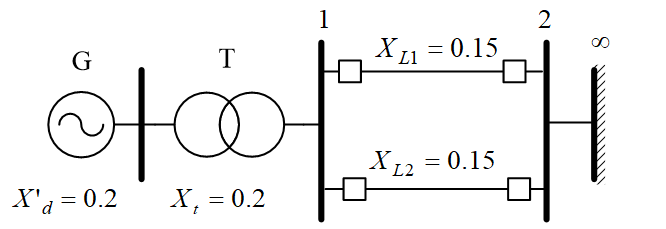

The reactances marked in the single-line diagram are given on a common base. Initially, the electrical power system is working in steady-state and the synchronous generator delivers an active power of 0.6 per unit, power factor of 0.8 behind the infinite busbar and the voltage is *V*= 1.0 p.u.

**[QUESTION] **

- Assume a disturbance is inserted at *t* = 0, the disturbance is a step decrease on 10% of the mechanical power from the previous value in steady-state. Determine if the system is stable. In case of being stable, indicate the final angle of operation in stable state

Created by: Professor Francisco Gonzalez-Longatt, January 2020. fglongatt@fglongatt.org

V00=1.0;                        % V00: Infinite bus voltage (pu)

Calculating the Equivalent reactance

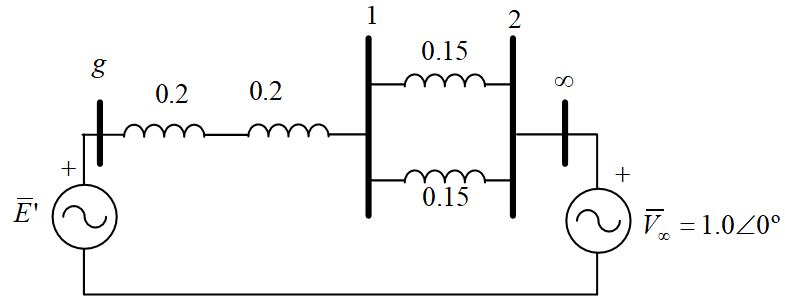

Xg0 = 0.2+0.2+0.15/2;                     % Xg0: Equivalent reactance (pu)
fprintf(' Xg∞ = %5.5f degrees',Xg0)

 Xg∞ = 0.47500 degrees

S = 0.6/0.8 * exp(i*acos(0.8));           % S: Apparent power (pu) 
fprintf(' S = ( %5.5f + j%5.5f ) pu',real(S),imag(S))

 S = ( 0.60000 + j0.45000 ) pu

fprintf(' S = ( %5.5f ∠ %5.5f° ) pu',abs(S),angle(S) * 180/pi)

 S = ( 0.75000 ∠ 36.86990° ) pu

Pmec0 = real(S);                          % Pmec0 : Initial Mechanical Power (pu)
fprintf(' Pmec0 = %5.5f degrees',Pmec0)

 Pmec0 = 0.60000 degrees

I=conj(S);                                % I: Current (pu)
fprintf(' I = ( %5.5f ∠ %5.5f° ) pu',abs(I),angle(I) * 180/pi)

 I = ( 0.75000 ∠ -36.86990° ) pu

E= i * Xg0 * I + V00;                     % E: Internal voltage of synchronous machine (pu)
fprintf(' E = ( %5.5f ∠ %5.5f° ) pu',abs(E),angle(E) * 180/pi)

 E = ( 1.24676 ∠ 13.21421° ) pu

Calculationg the initial angle (delta0, δ0):

delta0 = angle(E);
fprintf(' Delta0 = %5.5f radians',delta0)

 Delta0 = 0.23063 radians

fprintf(' Delta0 = %5.5f degrees',delta0 * 180/pi)

 Delta0 = 13.21421 degrees

Calculating the maximum power and defining the power-angle curve (P-δ):

Pmax1 = abs(V00) * abs(E) / Xg0;              % Pmax1: Maximum electrical 
fprintf(' Pmax1 = %5.5f pu',Pmax1);

 Pmax1 = 2.62476 pu

Pmec1 = 0.90 * (Pmec0);                       % Pmec1: 10% reduction of the initial Pmec0
fprintf(' Pmec1 = %5.5f pu -10 percent reduction of the initial Pmec0- ',Pmec1)

 Pmec1 = 0.54000 pu -10 percent reduction of the initial Pmec0- 

delta1 = asin(Pmec1/Pmax1);                   % delta1: InitiaL power angle, delta1
fprintf(' delta1 = %5.5f radians',delta1)

 delta1 = 0.20721 radians

fprintf(' delta1 = %5.5f degrees',delta1 * 180/pi)

 delta1 = 11.87241 degrees

% USING SYMBOLIC MATHEMATIC IN MATLAB
syms delta deltamax 
fprintf(' Power-angle characteristic')

 Power-angle characteristic

Pelec = Pmax1*sin(delta)

$$Pelec = \frac{\sqrt{39793}\,\sin\left(\delta \right)}{76}$$

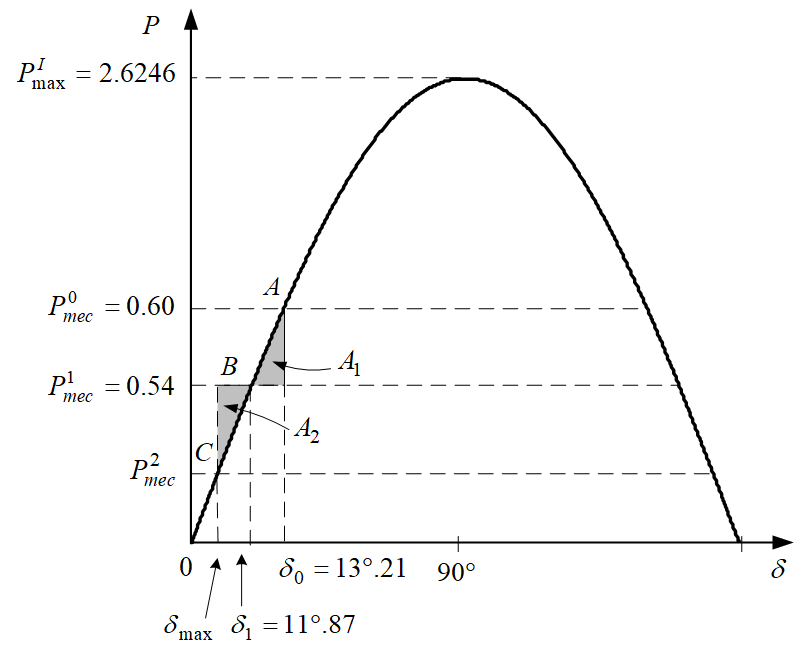

Defining **Area 1:**

fprintf(' Pacel 1: Acelerating Power 1')

 Pacel 1: Acelerating Power 1

Pacel1 = Pelec - Pmec1    % where Pelec > Pmec

$$Pacel1 = \frac{\sqrt{39793}\,\sin\left(\delta \right)}{76}-\frac{27}{50}$$

fprintf(' A1: Acelerating Area')

 A1: Acelerating Area

A1=int(Pacel1,delta1,delta0)

$$A1 = -\frac{\sqrt{39793}\,\left(\cos\left(\frac{8309371846844007}{36028797018963968}\right)-\cos\left(\frac{1866406046230189}{9007199254740992}\right)\right)}{76}-\frac{22781186871927777}{1801439850948198400}$$

A1=double(A1)

A1 = 7.0317e-04

Defining **Area 2:**

fprintf(' Pacel 2: Deacelerating Power 2')

 Pacel 2: Acelerating Power 2

Pacel2 = Pmec1 - Pelec    % where Pmec > Pelec

$$Pacel2 = \frac{27}{50}-\frac{\sqrt{39793}\,\sin\left(\delta \right)}{76}$$

fprintf(' A2: Deacelerating Area')

 A2: Deacelerating Area

A2=int(Pacel2,deltamax,delta1)

$$A2 = \frac{50392963248215103}{450359962737049600}-\frac{\sqrt{39793}\,\left(\cos\left(\mathrm{deltamax}\right)-\cos\left(\frac{1866406046230189}{9007199254740992}\right)\right)}{76}-\frac{27\,\mathrm{deltamax}}{50}$$

**Equal area creiteria**

fprintf(' Equation defining the Equal Area')

 Equation defining the Equal Area

EAC = A2 - A1

$$EAC = \frac{6409764237734647859}{57646075230342348800}-\frac{\sqrt{39793}\,\left(\cos\left(\mathrm{deltamax}\right)-\cos\left(\frac{1866406046230189}{9007199254740992}\right)\right)}{76}-\frac{27\,\mathrm{deltamax}}{50}$$

deltamax =solve(EAC)

$$deltamax = 0.18383236671539081520651707737895$$

deltamax = double(deltamax);
fprintf(' Deltamax = %5.5f radians',deltamax)

 Deltamax = 0.18383 radians

deltamaxDeg = deltamax*180/pi;
fprintf(' Deltamax = %5.5f degrees',deltamaxDeg)

 Deltamax = 10.53282 degrees